**Abgabe Phase 1**

Aufgabe 2: Pendel mit Federaufhängung

Gruppe E

Ausgeführt von: Abdulhamid Baghdadi, BSc

Ausgeführt von: Markus Keck, BSc

BegutachterIn: DI(FH) Anton Mario Puhwein, MSc

Wien, XXX

## Analytische Modellbeschreibung

Text

## Herleitung der DGL durch die newtonsche Schnittmethode

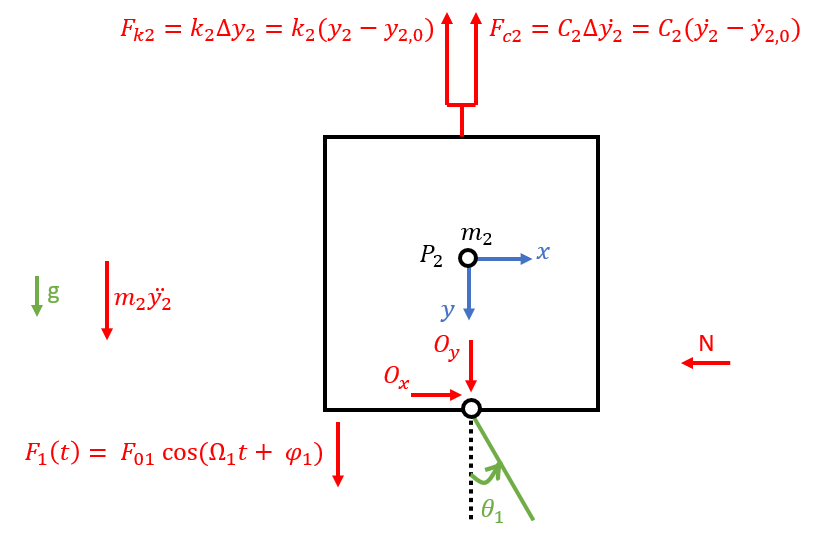

Symbol definitions

syms t theta(t) y_2(t) ...
    x_1 x_3 dot_x_1 dot_x_2 dot_x_3 dotdot_x_1 dotdot_x_2 dotdot_x_3 ...
    y_1 y_3 dot_y_1 dot_y_2 dot_y_3 dotdot_y_1 dotdot_y_2 dotdot_y_3 ...
    l_1 I_1 m_1 m_2 m_3 k_2 k_1 c_2 c_1 ...
    F_1(t) M_1(t) omega_1 phi_1 F_01 M_01 ...
    M_k1 F_k2 M_c1 F_c2 Sigma_M ...
    A_x A_y O_x O_y ...
    g Q_theta Q_y

sympref('AbbreviateOutput', false)

ans = logical
   0


   

M_1(t) = M_01*cos(omega_1*t + phi_1);
F_1(t) = F_01*cos(omega_1*t + phi_1);
M_k1 = k_1*theta;
M_c1 = c_1*diff(theta, t);
F_k2 = k_2*y_2;
F_c2 = c_2*diff(y_2, t);

x_3 = l_1*sin(theta);
y_3 = y_2 + l_1*cos(theta);
x_1 = l_1/2*sin(theta);
y_1 = y_2 + l_1/2*cos(theta);
diff(x_1, t, 2);
diff(x_3, t, 2);
diff(y_1, t, 2);
diff(y_3, t, 2);

Sigma_M = M_k1 + M_c1 - M_1;

%Das 2. Newtonsche Gesetz um den Schwerpunkt P3:
%eq_1 = m_3*diff(x_3, t, 2) == -A_x;
%A_x = solve(eq_1, A_x);

%eq_2 = m_3*diff(y_3, t, 2) == m_3*g - A_y;
%A_y = solve(eq_2, A_y)

Das 2. Newtonsche Gesetz um den Schwerpunkt P1:

eq_3 = A_y == (m_1 + m_3)*g - m_1*diff(y_1, t, 2) - m_3*diff(y_3, t, 2);
A_y = solve(eq_3, A_y)

$$A\_y = g\,\left(m_{1}+m_{3}\right)+m_{3}\,\left(l_{1}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+l_{1}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)+m_{1}\,\left(\frac{l_{1}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+\frac{l_{1}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}\right)$$

Drallsatz um den Lagerpunkt O:

eq_4 = I_1*diff(theta, t, 2) == -m_1*g*sin(theta) -Sigma_M - sin(theta)*l_1*A_y + cos(theta)*l_1*A_x;
simplify(eq_4)

$$ans(t) = M_{01}\,\cos\left(\varphi_{1}+\omega_{1}\,t\right)+A_{x}\,l_{1}\,\cos\left(\theta \left(t\right)\right)=c_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+k_{1}\,\theta \left(t\right)+I_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l_{1}\,\sin\left(\theta \left(t\right)\right)\,\left(g\,\left(m_{1}+m_{3}\right)+m_{3}\,\left(l_{1}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+l_{1}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)+m_{1}\,\left(\frac{l_{1}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+\frac{l_{1}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}\right)\right)+g\,m_{1}\,\sin\left(\theta \left(t\right)\right)$$

Das 2. Newtonsche Gesetz um den Schwerpunkt P2:

eq_5 = m_2*diff(y_2, t, 2) == m_2*g + O_y + F_1 - F_k2 - F_c2;
simplify(eq_5)

$$ans(t) = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+c_{2}\,\frac{\partial }{\partial t}y_{2}\left(t\right)+k_{2}\,y_{2}\left(t\right)=O_{y}+F_{01}\,\cos\left(\varphi_{1}+\omega_{1}\,t\right)+g\,m_{2}$$

Lagrange equations

V = k_1*theta^2/2 + k_2*y_2^2/2 + l_1*g*cos(theta)*(m_1/2 + m_3) ...
  - g*y_2*(m_1 + m_2 + m_3);


% + m_1/2*( (l_1/2*diff(theta)*cos(theta))^2 + (diff(y_2) - l_1/2*diff(theta)*sin(theta))^2) ...
T = I_1/2*diff(theta)^2 ...
+ m_1/2*( diff(x_1,t)^2 + diff(y_1,t)^2 ) ...
+ m_2/2*(diff(y_2, t))^2 ...
+ m_3/2*( diff(x_3,t)^2 + diff(y_3,t)^2 );


Q_theta = M_1 - c_1*diff(theta);
Q_y = F_1 - c_2*diff(y_2);

eq_6 = diff( diff(T, diff(theta(t),t)), t) - diff(T,theta) + diff(V, theta) == Q_theta;
eq_7 = diff( diff(T, diff(y_2(t),t)), t) - diff(T,y_2) + diff(V, y_2) == Q_y;
simplify(eq_6)

$$ans(t) = 4\,M_{01}\,\cos\left(\varphi_{1}+\omega_{1}\,t\right)+4\,g\,l_{1}\,\sin\left(\theta \left(t\right)\right)\,\left(\frac{m_{1}}{2}+m_{3}\right)+2\,l_{1}\,m_{1}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+4\,l_{1}\,m_{3}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)=4\,c_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+4\,k_{1}\,\theta \left(t\right)+4\,I_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+{l_{1}}^{2}\,m_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+4\,{l_{1}}^{2}\,m_{3}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

simplify(eq_7)

$$ans(t) = 2\,m_{1}\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+2\,m_{2}\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+2\,m_{3}\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+2\,c_{2}\,\frac{\partial }{\partial t}y_{2}\left(t\right)+2\,k_{2}\,y_{2}\left(t\right)=2\,F_{01}\,\cos\left(\varphi_{1}+\omega_{1}\,t\right)+2\,g\,m_{1}+2\,g\,m_{2}+2\,g\,m_{3}+l_{1}\,m_{1}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+2\,l_{1}\,m_{3}\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l_{1}\,m_{1}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,l_{1}\,m_{3}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$


a1 = isolate(eq_5, diff(y_2, t, 2));
a2 = isolate(eq_6, diff(y_2, t, 2));

b1 = isolate(eq_4, diff(theta, t, 2));
b2 = isolate(eq_6, diff(theta, t, 2));
simplify(b1);
simplify(b2);


isequaln(a1, a2);
isequaln(b1, b2);